## **膜厚計測の自動データ処理**

 自動膜厚計は計測する時1列で順番通り記録しているため，自分のExcelファイルに正しい位置に入れ込むために，この一列を分けないといけない．

　現在の例は，Sさんの膜厚計測データがある．母材孔回りの無機ジンクの膜厚を測りました．

不変な条件は：ボルト孔回り4箇所5回ずつ計測していな．回数=4x5x2x2x4=**320**

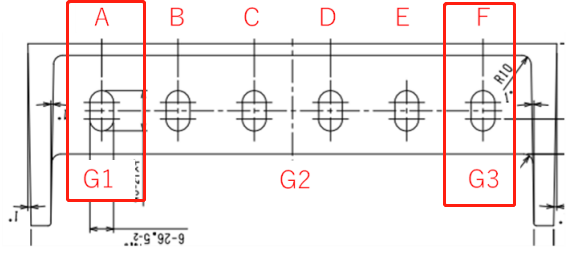     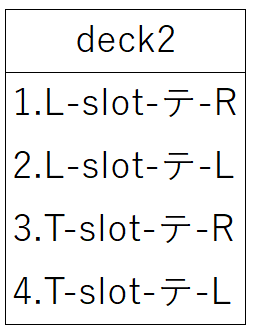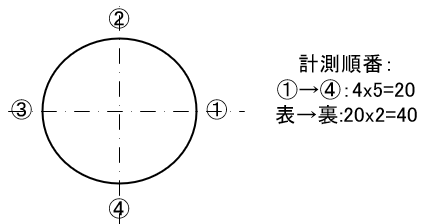

 目標**：**使えるデータになれるように，試験体ごと，ボルトごと，測る位置ごとに分けたい

**1．csvファイルの読み込む**

f = readmatrix('deck2.CSV')     %4列320行の行列を読み込まれた．

f =        NaN    1.0000  208.2000       NaN
       NaN    2.0000  177.7000       NaN
       NaN    3.0000  179.3000       NaN
       NaN    4.0000  161.1000       NaN
       NaN    5.0000  181.2000       NaN
       NaN    6.0000  183.4000       NaN
       NaN    7.0000  135.3000       NaN
       NaN    8.0000  162.9000       NaN
       NaN    9.0000  127.4000       NaN
       NaN   10.0000  135.1000       NaN


f = f(:,3)                      %いらない列数を捨てる

f =   208.2000
  177.7000
  179.3000
  161.1000
  181.2000
  183.4000
  135.3000
  162.9000
  127.4000
  135.1000


%f = f'
data = reshape(f,5,[])          %行列の形変わる

data =   208.2000  183.4000  136.0000  192.7000  191.8000  173.8000  139.7000  182.0000  177.9000  169.7000  149.9000  135.5000  173.3000  178.3000  143.6000  169.5000  193.1000  164.5000  161.3000  157.2000  187.0000  146.9000  147.6000  150.7000  202.4000  124.7000  149.9000  154.1000  158.7000  159.7000  148.4000  159.5000  160.1000  153.7000  149.8000  161.9000  158.1000  161.8000  128.1000  130.5000  161.5000  151.8000  135.8000  159.1000  192.5000  151.7000  140.9000  165.0000  188.2000  185.2000
  177.7000  135.3000  152.5000  181.5000  182.1000  178.7000  126.9000  113.9000  193.1000  163.3000  153.9000  151.6000  155.0000  144.8000  176.2000  170.0000  155.2000  153.3000  189.7000  150.9000  171.3000  166.1000  158.6000  164.5000  155.3000  129.9000  138.7000  171.5000  181.1000  143.8000  132.8000  168.6000  158.2000  129.4000  165.8000  154.1000  139.9000  160.9000  123.1000  142.9000  179.1000  155.1000  146.9000  156.3000  174.4000  113.2000  128.2000  194.2000  199.5000  

[~,a] = size(data)                 %行数を取得する

a = 5

k = 1

k = 1

for i=1:a
    if rem(i,5) == 0
        t = [data(i-4:i-1,:);s;]
        k = k+1
    end
end

関数または変数 's' が認識されません。